# 1. **Introduction to Optimisation**

## **1.1 What is Optimisation?**

- Optimisation deals with the following problem – choose the value x such that some quantity F, which depends on x, is a ***minimum***. Here, F is referred to as the ***objective function***.

- In mathematical terms, we express this problem as: $\min_{x} F(x)$

- In seeking the minimum of $F(x)$ we may often be restricted in the choice of $x$. Typically, there may be other quantities $C_i(x)$  whose value must be maintained within certain limits. These are called ***constraints***. 

- The variable $x$ may be a scalar or an n-vector (i.e. $\textbf{x} = [x_1 \quad x_2 \quad  \cdots \quad x_n ]^T$). 

- Notice that vectors are represented with bold font, while scalars are not. Also, matrices are generally represented with bold capital font. Alternatively, vectors can be represented using an underline, i.e. $\underline{x}$.

- Hence, the full expression of the problem in standard form is as follows:

            
$$\min \qquad F(\textbf{x}), \textbf{x} \in \Re^n$$


            $\mathrm{subject}\quad \mathrm{to} \qquad C_i(\textbf{x})=0; i=1,2 \cdots ,k$                     (equality constraints)

                                     $C_j(\textbf{x})\geq 0; j=k+1,k+2 \cdots ,m$       (inequality constraints)

            where $m$ represents the total number of constraints.

- Note that if $m=0$, then we are dealing with an ***unconstrained*** optimisation problem, otherwise, if $m \neq 0$, then we have a ***constrained ***optimisation problem.

- Furthermore, note that the ***maximum*** of a function $F(\textbf{x})$ is the same as the minimum of the negative of the function, i.e. – $F(\textbf{x})$. In other words:

            
$$\max F(\textbf{x})\equiv \min (-F(\textbf{x}))
$$


            
$$C_i(\textbf{x})\leq 0 \equiv -C_i(\textbf{x})\geq 0$$


### **Engineering Examples of Optimisation**

- In its broadest sense, optimisation can be applied to solve almost any (if not all) engineering problems.

- Some typical applications that use optimisation include:

- Design of aircraft and aerospace structures for minimum weight.

- Design of water resources systems for maximum benefit.

- Design of pumps, turbines and heat transfer equipment for maximum efficiency.

- Optimal design of electrical networks.

- Selection of a site for an industry.

- Analysis of statistical data and building empirical models from experimental results to obtain the most accurate representation of the physical phenomenon.

- Allocation of resources or services among several activities to maximise benefit.

- Controlling the waiting and idle times and queueing in production lines to reduce the costs.

- Optimum design of control systems.

- *These example applications clearly illustrate the wide scope of optimisation!*

### **An Optimisation Example**

- $x$Consider the function $F(x) = (x^3 - 3x^2)^{\frac{1}{3}}$, where $x
$ is a scalar value (i.e. n = 1 in terms of the vector **x**!).

syms x;

% Define the function
F = (x^3 - 3*x^2)^(1/3);

% Compute the first derivative and solve for critical points
F_prime = diff(F, x);
crit_points = double(solve(F_prime, x));

% Compute the second derivative
F_double_prime = diff(F_prime, x);

% Analyze the nature of critical points
for point = crit_points'
    if double(subs(F_double_prime, x, point)) > 0
        fprintf('x = %f is a local minimum.\n', point);
    end
end

% Determine global minimum
[min_value, min_index] = min(double(subs(F, x, crit_points)));
global_min_point = crit_points(min_index);

fprintf('The global minimum of F(x) occurs at x = %f with a value of %f\n', global_min_point, min_value);

The global minimum of F(x) occurs at x = 2.000000 with a value of 0.793701


x_values = linspace(-2, 5, 1000);
F_values = double(subs(F, x, x_values));
% Create plot of x_values and F_values
hold on
h = plot(x_values,F_values,"DisplayName","F_values");


% Add xlabel, ylabel, title, and legend
xlabel("x_values")
ylabel("F_values")
title("F_values vs. x_values")
% Highlight the global minimum with a blue circle
plot(global_min_point, min_value, 'bo', 'MarkerSize', 8, 'DisplayName', 'Global Minimum');

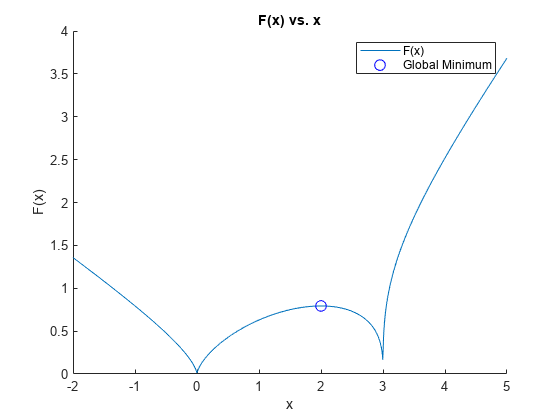

legend

xlim([-2.00 5.00])
ylim([0.00 4.00])
legend(["F(x)","Global Minimum"])
title("F(x) vs. x")
xlabel("x")
ylabel("F(x)")